24-774: Lab 1

Due Sept 20

Team: 

Pranav Narahari

Keitaro Nishimura

Kyshalee Vazquez-Santiago

Emma Benjaminson

Notes on Plant Model and Reference: 

Yaw should have amplitude $\pi$/4 rad and freq 0.5 rad/s 

Pitch should have amplitude $\pi$/6 rad and freq 0.4 rad/s

## Preliminaries

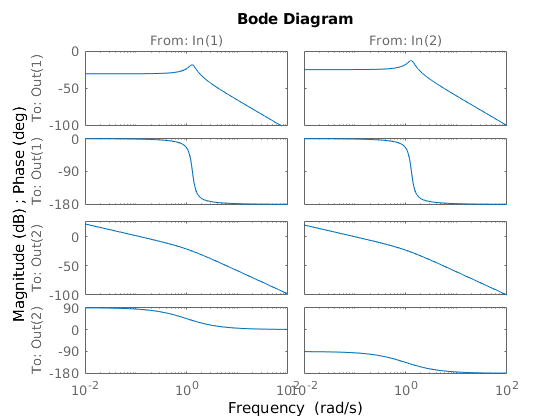

quanser_aero_parameters
quanser_aero_state_space

% nominal plant model 
Gnom = ss(A, B, C, D) ; 
bode(Gnom) ; 

% bodemag(Gnom) ;

The outputs to channel 1 both show typical second order behavior with a resonant peak at about 1.3 rad/s. The output to channel 2 seems to be a proper system with a pole and zero, with first order characteristics. I cannot see anything that I would call "unusual". But I thought that the Bode plots on the diagonals (1,1) and (2,2) would be more similar and the off-diagonal plots would be more chaotic? Why are all the bodes for a particular output (regardless of the input) very similar? 

**WHAT ARE CHANNELS 1 AND 2 ON INPUT AND OUTPUT REPRESENTING?**

% saturation nonlinearity to limit control voltages to +/- 25V
Wu = eye(2)*1/25 ; 


Notes on Simulink model: I am having trouble tuning the PID controllers because they do not seem to affect my plant channels independently. Am I doing something wrong or is this the effect of coupling at work? 